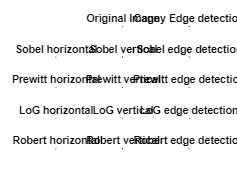

im = imread("MRI Brain Gray.jpg");
im = rgb2gray(im);
subplot(532);
imshow(im);title("Original Image");

%filters
%sobel
sx = [-1 0 1;-2 0 2;-1 0 1];
sy = [1 2 1;0 0 0;-1 -2 -1];

%prewitt
px = [1 0 -1;1 0 -1;1 0 -1];
py = [-1 -1 -1;0 0 0;1 1 1];

%log
lx = [-1 -1 -1;1 -8 1;1 1 1];
ly = [-1 1 1;-1 -8 1;-1 1 1];

%roberts
rx = [0 0 0;0 1 -1;0 -1 1];
ry = [0 0 0;0 -1 1;0 -1 1];

subplot(533);
a1 = edge(im,"canny");
imshow(a1);title("Canny Edge detection");


subplot(534);
a = uint8(convolution(double(im),sx));
imshow(a);title("Sobel horizontal");
subplot(535);
b = uint8(convolution(double(im),sy));
imshow(b);title("Sobel vertical");
c = sqrt(double(a).^2 + double(b).^2);
subplot(536);
imshow(uint8(c));title("Sobel edge detection");

subplot(537);
d = uint8(convolution(double(im),px));
imshow(d);title("Prewitt horizontal");
subplot(538);
e = uint8(convolution(double(im),py));
imshow(e);title("Prewitt vertical");
f = sqrt(double(d).^2 + double(e).^2);
subplot(539);
imshow(uint8(f));title("Prewitt edge detection");

subplot(5,3,10);
g = uint8(convolution(double(im),lx));
imshow(g);title("LoG horizontal");
subplot(5,3,11);
h = uint8(convolution(double(im),ly));
imshow(h);title("LoG vertical");
i = sqrt(double(g).^2 + double(h).^2);
subplot(5,3,12);
imshow(uint8(i));title("LoG edge detection");

subplot(5,3,13);
j = uint8(convolution(double(im),rx));
imshow(j);title("Robert horizontal");
subplot(5,3,14);
k = uint8(convolution(double(im),ry));
imshow(k);title("Robert vertical");
l = sqrt(double(a).^2 + double(b).^2);
subplot(5,3,15);
imshow(uint8(l));title("Robert edge detection");

function y = convolution(a,b)
[r,c] = size(a);
y = zeros(r,c);
for i = 1:r-2
    for j = 1:c-2
       y(i,j) = sum(sum(a(i:i+2,j:j+2).*b));
    end
end
end